ke = 0.4987;
km = ke; 
R =  8.8696;
L = 0.0047;
J = 0.0023;
r=0.028;
B=0.21;
h=80;
xlim([-h h])
ylim([-h h])

data=readmatrix('lab4_data\non_linear_(-60 0)_(30 35).txt');
K1=30;
K2=35;

goal_x=-60;
goal_y=0;

X=data(:,1);
Y=data(:,2);

simout=sim('VPD_lab_4_nonlinear')

simout =   Simulink.SimulationOutput:

                      V: [1x1 timeseries] 
                   tout: [113814x1 double] 
                      x: [1x1 timeseries] 
                      y: [1x1 timeseries] 

     SimulationMetadata: [1x1 Simulink.SimulationMetadata] 
           ErrorMessage: [0x0 char] 


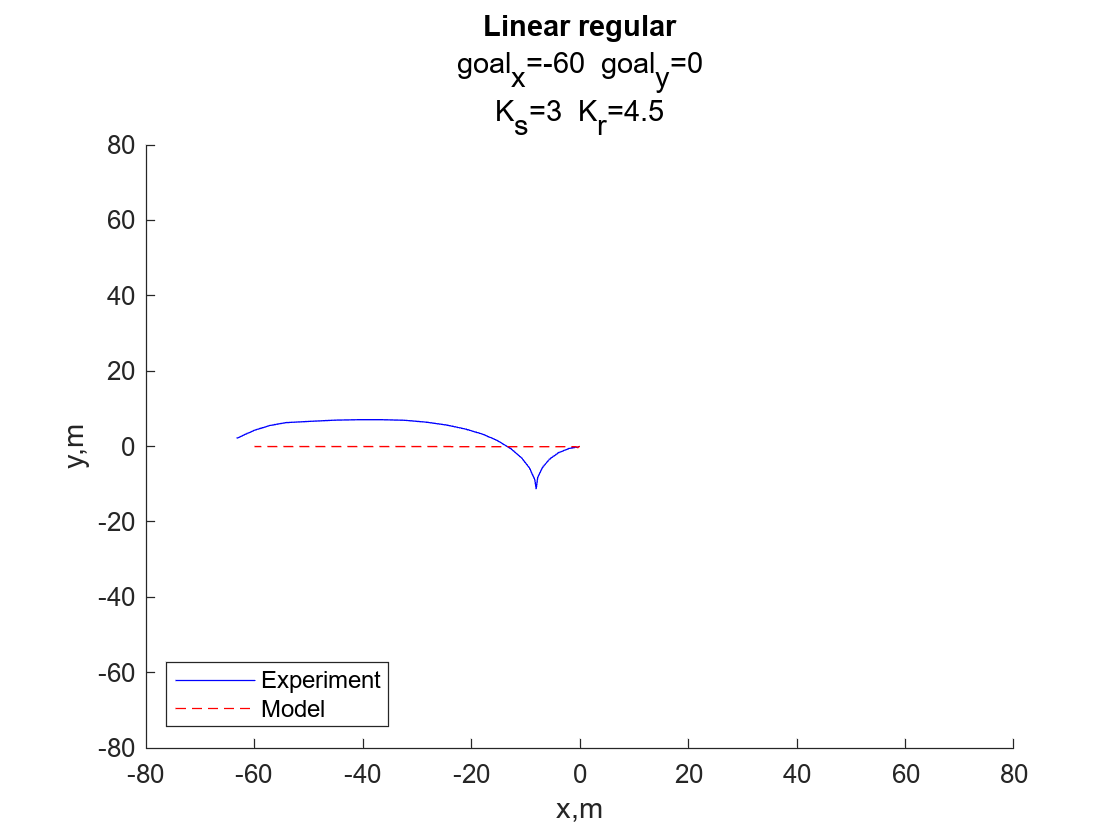

hold on
plot(X,Y,'b')
plot(simout.x.Data, simout.y.Data,'r--')
h1=strcat('goal_x=',string(goal_x),'  goal_y=', string(goal_y));
h2 = strcat('K_s=',string(K_s),'  K_r=', string(K_r));
title('Linear regular',{h1,h2})
xlabel('x,m');
ylabel('y,m');
legend('Experiment', 'Model','Location','southwest')
folderPath = 'D:\VPD_lab_4\Plot';

fileName = 'plot_non_linear_(0 80)_(3 4,5)';

fullPath = fullfile(folderPath, fileName);

saveas(gcf, fullPath, 'png');

hold off